# Gradient Descent 2D

% x0 = 1x2 vector
% dfdx: 2 parameters --> 1x2 vector = gradient
% f: 2 parameters --> scalar real number

function [xs,fs,n,converged] = gradient_descent2d(conjugate,x0,y0,f,dfdx,alpha0,rho,sigma,N,tol)
    converged =  false;
    n = 1;

    xs = zeros(N+1,2);
    xs(1,:) = [x0 y0];

    fs = zeros(1,N+1);
    fs(1) = f(x0,y0);
    
    gs = zeros(N+1,2);
    gs(1,:) = dfdx(x0,y0);

    ds = zeros(N+1,2);
    ds(1,:) = -1.*gs(1,:);

    if(norm(gs(1,:))<tol)
        error("at minimum already");
    end
    
    alpha = alpha0;

    % n = number of computed x in array points 
    %   = index of last element in array points
    % n-1 = last index of computed x = number of completed steps

    %h = animatedline;
    %addpoints(h,xs(1,1),xs(1,2),fs(1));
    %drawnow;


    while n-1<N
        dhda = ds(n,:)*gs(n,:)';

        xs(n+1,:) = xs(n,:) + alpha * ds(n,:);
        fs(n+1) = f(xs(n+1,1),xs(n+1,2));

        while fs(n+1)>=fs(n)+alpha*sigma*dhda
            alpha = alpha*rho;
            xs(n+1,:) = xs(n,:) + alpha*ds(n,:);
            fs(n+1) = f(xs(n+1,1),xs(n+1,2));
        end

        n = n+1;
        gs(n,:) = dfdx(xs(n,1),xs(n,2));

        %addpoints(h,xs(n,1),xs(n,2),fs(n));
        %drawnow;

        if(norm(gs(n,:))<tol*(1+norm(gs(1,:))))
            converged = true;
            break
        end
        
        ds(n,:) = -1.*gs(n,:);
        if conjugate
            ds(n,:) = -1.*gs(n,:) + (((gs(n,:)-gs(n-1,:))*gs(n,:)')/norm(gs(n-1,:))).*ds(n-1,:);
        end

        alpha = (gs(n-1,:)*ds(n-1,:)')*alpha/(gs(n,:)*ds(n,:)');
    end

    xs = xs(1:n,:);
    fs = fs(1:n);
    %gs = gs(1:n,:);
end

## plot

function plot_function(ax,f,xmin,xmax,ymin,ymax)
    density = 10;
    xrange = xmax-xmin;
    yrange = ymax-ymin;

    [X,Y] = meshgrid(linspace(xmin,xmax,density*xrange),linspace(ymin,ymax,density*yrange));
    Z = f(X,Y);

    %surfc(ax,X,Y,Z,'EdgeColor','none');
    surf(ax,X,Y,Z);
    shading flat;
    %colorbar;
end

function plot_function_descent(ax,xs,fs)
    plot(xs(1,1),xs(1,2),'.r');
    n = length(xs);

    for i=2:n
        plot3(ax,[xs(i-1,1) xs(i,1)],[xs(i-1,2) xs(i,2)],[fs(i-1) fs(i)],'-k','LineWidth',1);
        if(i==n)
            plot3(ax,xs(i,1),xs(i,2),fs(i),'.g','MarkerSize',9);
        else
            plot3(ax,xs(i,1),xs(i,2),fs(i),'.k','MarkerSize',9);
        end
    end
end

function plot_contours(ax,f,xmin,xmax,ymin,ymax)
    density = 10;
    xrange = xmax-xmin;
    yrange = ymax-ymin;

    [X,Y] = meshgrid(linspace(xmin,xmax,xrange*density),linspace(ymin,ymax,yrange*density));
    Z = f(X,Y);

    contourf(ax,X,Y,Z);
end

function plot_contour_descent(ax,xs)
    n = length(xs);
    plot(ax,xs(1,1),xs(1,2),'.r','MarkerSize',9);
    for i=2:n
        plot(ax,[xs(i-1,1) xs(i,1)],[xs(i-1,2) xs(i,2)],'-k','LineWidth',1);
        if(i==n)
            plot(ax,xs(i,1),xs(i,2),'.g','MarkerSize',9);
        else
            plot(ax,xs(i,1),xs(i,2),'.k','MarkerSize',9);
        end
    end
end

function plot_all(ax1,ax2,conjugate,x0,y0,f,dfdx,alpha0,rho,sigma,N,tol,xmin0,xmax0,ymin0,ymax0)
    [xs,fs,n,converged] = gradient_descent2d(conjugate,x0,y0,f,dfdx,alpha0,rho,sigma,N,tol);

    ratio = 0.6;
    x = xs(:,1);
    y = xs(:,2);
    xmin = min(min(x) - ratio*abs(min(x)),xmin0);
    xmax = max(max(x) + ratio*abs(max(x)),xmax0);
    ymin = min(min(y) - ratio*abs(min(y)),ymin0);
    ymax = max(max(y) + ratio*abs(max(y)),ymax0);

    plot_function(ax1,f,xmin,xmax,ymin,ymax);
    plot_function_descent(ax1,xs,fs);

    plot_contours(ax2,f,xmin,xmax,ymin,ymax);
    plot_contour_descent(ax2,xs);
    colorbar(ax2);

    fprintf("(x,y) = (%d,%d)\n",x(end),y(end));
    if converged
        fprintf("Converged in %d steps\n",n);
    else
        fprintf("Not converged\n");
    end
end

## Variables

function a = f(x,y)

    % example 6.2
    %tmp = 4.*(x-2.*y).^2+(x+2.*y).^2+1/50.*(4.*(x-2.*y).^4 + (x+2.*y).^4);
    %a = log(1+tmp);

    % banana function (rossenbrocks)
    % a = (2.-x).^2+3.*(y-x.^2).^2;

    % another banana function
    % a = y.*sin(x)-x.*cos(y);

    %a = sin(x.^2)+cos(y.^2);
    
    %a = x.^2+y.^2;

    a = x.*y + 8./x + 27./y;
end

function d = dfdx(x,y)
    d = zeros(1,2);

    % example 6.2
    %tmp = 4*(x-2*y)^2+(x+2*y)^2+1/50*(4*(x-2*y)^4 + (x+2*y)^4);
    %d(1) = (1/(1+tmp)).*(8*(x-2*y)+2*(x+2*y)+1/25*(8*(x-2*y)^3+2*(x+2*y)^3));
    %d(2) = (1/(1+tmp)).*(-16*(x-2*y)+4*(x+2*y)+1/25*(-16*(x-2*y)^3+4*(x+2*y)^3));
    
    % another banana function
    %d(1) = y.*cos(x)-cos(y);
    %d(2) = sin(x)+x.*sin(y);
    
    % banana function (rossenbrocks)
    %d(1) = -2.*(2-x) - 12.*(y-x.^2).*x;
    % d(2) = 6.*(y-x.^2);

    %d(1) = cos(x.^2).*2.*x;
    %d(2) = -sin(y.^2).*2.*y;

    d(1) = y - 8./x.^2;
    d(2) = x - 27./y.^2;
end

alpha0 = 1;
rho = 0.5;
sigma = 0.1;
N = 100;
tol = 2e-7;

## Driver

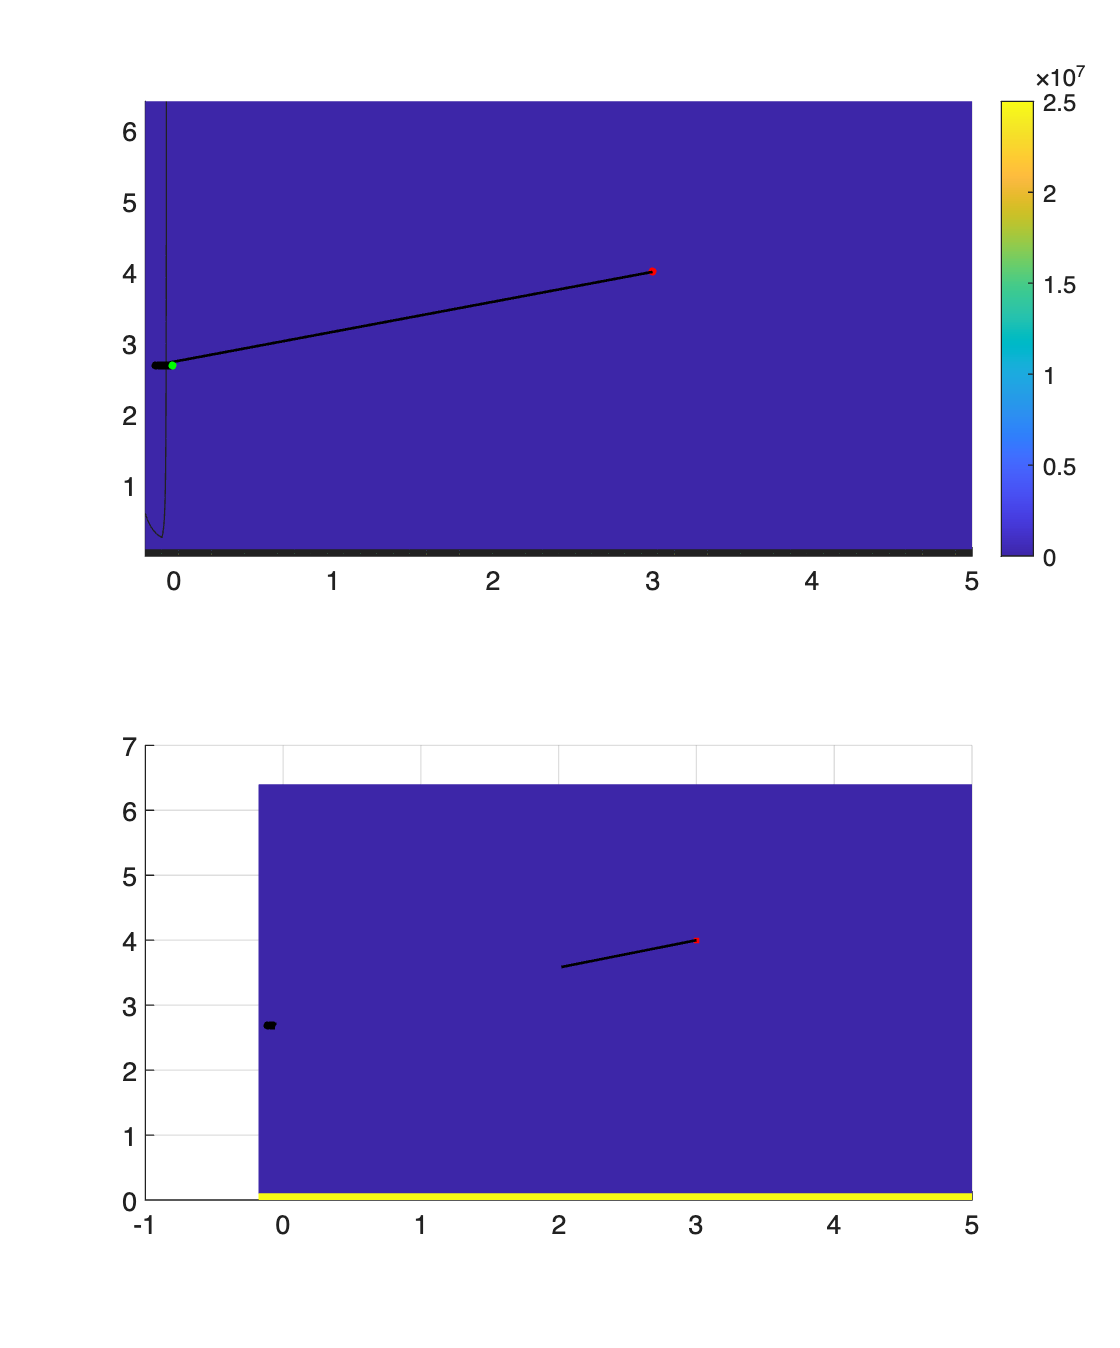

(x,y) = (-6.480662e-03,2.687750e+00)
Not converged


h = figure;
h.Position(4) = h.Position(4)*2;
tiledlayout;
nexttile;
ax1 = gca;
nexttile;
ax2 = gca;
%ax1 = axes('Position',[0.1 0.1 0.7 0.7]);
%ax2 = axes('Position',[0.8 0.8 0.7 0.7]);
hold(ax1,'on');
hold(ax2,'on');
grid(ax1,'on');
grid(ax2,'on');


xmin0 = 1e-6;
xmax0 = 5;
ymin0 = 1e-6;
ymax0 = 5;
x0 = 3;
y0 = 4;
conjugate = false;

plot_all(ax2,ax1,conjugate,x0,y0,@f,@dfdx,alpha0,rho,sigma,N,tol,xmin0,xmax0,ymin0,ymax0);